# Especies virtuales prueba

addpath Tool/VirtualSpeciesFunctions/
% addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 14.164855 seconds.


close all

% Occupation = [0.1 1];
% Samples = [10 50];
alpha = -3:1:-1; 
Occupation = 0.1:0.2:0.7;            % Ocupacion terreno
Samples = [25 50 100 1000];          % Número de puntos 
% Samples = [10 50 100 1000];        % Número de puntos 
% alpha = 0 : 0.25 : 1;              % Forma de muestreo

[OccupExp, SampExp, alpExp] = meshgrid(Occupation, Samples, alpha);
OccupExp = OccupExp(:);
SampExp = SampExp(:);
alpExp = alpExp(:);

% generacion de los puntos iniciales
N = 200;
Size = Dimensions.Dimensions(2);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Points = net(p, N);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Coeffs = net(p, N);

showVirtual = false;
showModel = false;
clustering = false;

Roc = zeros(length(SampExp), N); 
AreaMetric = zeros(length(SampExp), N);
DistanceMetric = zeros(length(SampExp), N);

tic
InfoInitialPoint = cell(N, 1);

[~, outland] = bnm_prep(T, Dimensions,showModel, 0.7, clustering, true);

for j = 1 : N
    InfoInitialPoint{j} = InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');

    for i = 1 : length(SampExp)
        i
        disp("alpha:" + alpExp(i))
        disp("Samples:" + SampExp(i))
        disp("Occupation:" + OccupExp(i))
        disp(" ")
        
        MapInfo = NicheGeneration(Dimensions, InfoInitialPoint{j}, OccupExp(i), showVirtual);
        NicheMap = MapInfo.Map;
        T = samplingVS(Dimensions, InfoInitialPoint{j}, MapInfo,...
            SampExp(i), alpExp(i), showVirtual, 'GenSP', true, true);
%         data = bnm_prep(T, Dimensions, false, 0.7, clustering);
        data = bnm_prep(T, Dimensions,showModel, 0.7, clustering);
        % modeling, save Metric
%         data = bnm_modeling(data, '', showModel);  
        data = bnm_modeling(data, '', showModel, 4, false, outland);  
        ModelMap = data.Map;
        VectorMet = MapMetric(NicheMap, ModelMap, false);
        AreaMetric(i, j) = VectorMet(1);
        DistanceMetric(i, j) = VectorMet(2);
        %% SACAR LA ROC %%
        Roc(i, j) = data.Roc;
%         drawnow
%         close all
    end
end

FinalTime = toc;
save("Congreso/Test_50_outland", "OccupExp", "SampExp", "alpExp", "DistanceMetric", "AreaMetric", "Points", "Coeffs", "Roc","FinalTime")

PointsAll = [];
CoeffsAll = [];
DistanceMetricAll = [];
AreaMetricAll = [];
RocAll = [];

for i = 1 : 2
%     load("OLDMODEL/Test/2_5KM/Test" + num2str(i) + "_SA_25_NoAlpha.mat")
    load("Congreso/Test_50_" + num2str(i) + ".mat")
    PointsAll = [PointsAll; Points];  
    CoeffsAll = [CoeffsAll; Coeffs];
    DistanceMetricAll = [DistanceMetricAll, DistanceMetric];
    AreaMetricAll = [AreaMetricAll, AreaMetric];
    RocAll = [RocAll, Roc];
end

Points = PointsAll;
Coeffs = CoeffsAll;
DistanceMetric = DistanceMetricAll;
AreaMetric = AreaMetricAll;
Roc = RocAll;

clear PointsAll CoeffsAll DistanceMetricAll AreaMetricAll RocAll

close all
MedianDistance = median(DistanceMetric');
MedianArea = median(AreaMetric');
TresArea = 0.7;
TresDist = 0.88;

subplot(2,1,1)

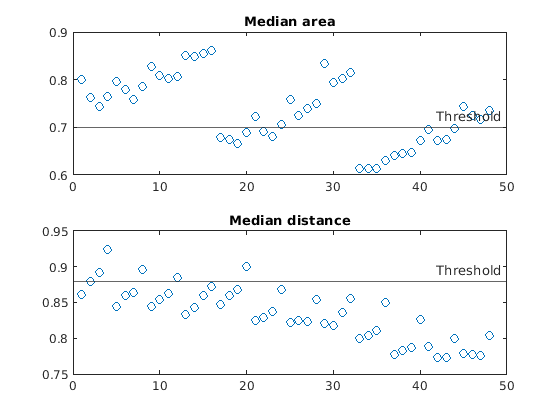

plot(MedianArea, 'o')
hold on
yline(TresArea,'-','Threshold');
title('Median area')

subplot(2,1,2)
plot(MedianDistance, 'o')
hold on
yline(TresDist,'-','Threshold');
title('Median distance')

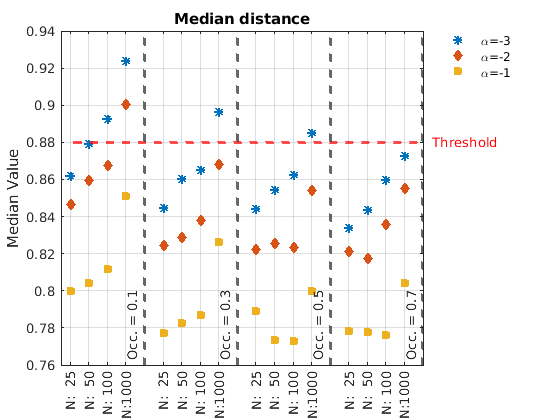

close all


B = num2str(SampExp(1:16));
S = repmat('N:',[16 1]);
E = repmat(' ',[16 1]);
alpha = -3:1:-1; 

A = rand(3,3);
cm = colormap(lines(size(A,1)));
Marker = ["*","d","s"];

xdata = [1:4, 6:9, 11:14, 16:19];

figure
for k = 1:3
    plot(xdata, MedianDistance(1+(k-1)*16:16+(k-1)*16), Marker(k),'linewidth',1.5,'MarkerFaceColor',cm(k,:), 'color',cm(k,:))
    hold on   
end

%% Threshold
xlim([0.5 20])
yl = yline(TresDist,'r--',' ','linewidth',2);
text(20.5,TresDist, 'Threshold','Color','r')
yl.LabelHorizontalAlignment = 'left';
yl.LabelVerticalAlignment = 'middle';

%% Occupation lines
for i=1:4
    xl = xline(xdata(i*4)+1,'--',{'Occ. = '+ string(OccupExp(i*4))},'linewidth',2);
    xl.LabelVerticalAlignment = 'bottom';
    xl.LabelHorizontalAlignment = 'left';
end

title("Median distance")
ylabel('Median Value')
grid on
    
lgnd = legend({'\alpha=-3','\alpha=-2','\alpha=-1'},'AutoUpdate','off');
set(lgnd,'color','none','EdgeColor', 'none','Location','bestoutside');
ax = gca;
ax.XTick= xdata;
xtickangle(90)
ax.XTickLabel = cellstr(num2str([S, B]));

Generate new model from existing virtual species

close all

alpExp = -1;
SampExp = 25;
OccupExp = 0.3;
% generacion de los puntos iniciales
N = 99;
Size = Dimensions.Dimensions(2);

load('/home/curie/MATLAB-Drive/VirtualSpecies/Pruebas1/Test_HenryRegressor.mat')

showVirtual = false;
showModel = false;
clustering = true;

Roc = zeros(1, N); 
AreaMetric = zeros(1, N);
DistanceMetric = zeros(1, N);

tic
InfoInitialPoint = cell(N, 1);

[~, outland] = bnm_prep(T, Dimensions,showModel, 0.7, clustering, true);

for j = 1 : N
    InfoInitialPoint{j} = InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');
        
    MapInfo = NicheGeneration(Dimensions, InfoInitialPoint{j}, OccupExp(i), showVirtual);
    NicheMap = MapInfo.Map;
    T = samplingVS(Dimensions, InfoInitialPoint{j}, MapInfo,...
            SampExp(i), alpExp(i), showVirtual, 'GenSP', true, true);
    data = bnm_prep(T, Dimensions,showModel, 0.7, clustering);
        % modeling, save Metric
    data = bnm_modeling(data, '', showModel, 4, false, outland);  
    ModelMap = data.Map;
    VectorMet = MapMetric(NicheMap, ModelMap, false);
    AreaMetric(j) = VectorMet(1);
    DistanceMetric(j) = VectorMet(2);
        %% SACAR LA ROC %%
    Roc(j) = data.Roc;
end